# Modelling the spread of the SARS-CoV-2 in China

**George Watkins, CMPT310, Simon Fraser University, 2020-03-05**

## Data preparation

Data Source:[1]

cases = read_china_cases_worldometers("china_cases.csv");
cases_dates = flip(table2array(cases(:,1)));
cases_count = flip(table2array(cases(:,2)));
data_point_number = length(cases_dates);

% Use days from first datapint as a numeric x axis, as days are the highest
% resolution available in the data
days_from_first_datapoint = days(cases_dates - repelem(min(cases_dates),data_point_number)');

## Exponential Growth

Let $Q\left(t\right)$ be the total number of reported cases at a point in time. Assuming that new cases are proportial to the population, with proportionality constant $r$, we have the differential equation:


$$\frac{dQ}{dt}=rQ$$


This equation has an analytic solution. For initial condition $Q\left(0\right)=Q_0$


$$Q\left(t\right)=Q_0 e^{\mathrm{rt}}$$


We have values of $Q\left(t\right)$for many days, those are the number of reported cases. This is data publicly available in [1]. 

What we want to find are $Q_0$ and $r$. So we find the best fit exponential curve through the data.

[a, b] = exponential_fit(days_from_first_datapoint, cases_count)

a = 1.5438e+03

b = 0.2196

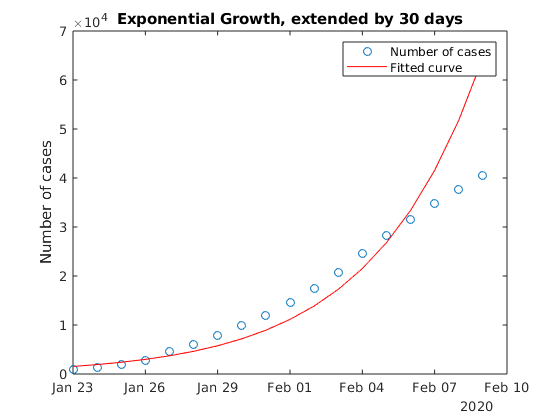


fitted_exponential_x = linspace(min(days_from_first_datapoint),max(days_from_first_datapoint),data_point_number);
fitted_exponential_y = a*exp(b*fitted_exponential_x);
format compact
plot(cases_dates,cases_count,'o',...
    cases_dates,fitted_exponential_y,'red')
legend('Number of cases','Fitted curve');
title("Exponential Growth, extended by "+extra_days +" days")
ylabel('Number of cases')

Doesn't seem to fit the data too well. This model is good in the early stages of the spread of a disease when the new case proprtionality assumption holds, but as time goes by cases start increasing more slowly.

## Logistic Growth

In logistic growth we assume that the proportionality constant $r$ of the exponential growth model decreases over time. So we replace it by a function of $Q$ that decreases as cases increase: $r-\alpha Q$.

The differential equation for this type of growth becomes:


$$\frac{dQ}{dt}=\left(r-\alpha Q\right)Q$$


The analytic solution can be expressed in the form:


$$Q\left(t\right)=\frac{Q_{\mathrm{inf}} }{\left(1+\mathrm{exp}\left(-\alpha \left(t-t_{\mathrm{half}} \right)\right)\right)}$$


Where $Q_{\mathrm{inf}}$ is the number of cases as $t\to \infty$, and $t_{\mathrm{half}}$ the time at which $Q\left(t\right)=\frac{Q_{\mathrm{inf}} }{2}$.

That is the form a helper library[2] uses. So we can use it to fit a curve of such form to the data.

 addpath fit_logistic
[ Qpre, p] = fit_logistic(days_from_first_datapoint,cases_count);

thalf = p(1), Qinf = p(2), alpha = p(3)

thalf = 12.1724

Qinf = 5.0361e+04

alpha = 0.2866

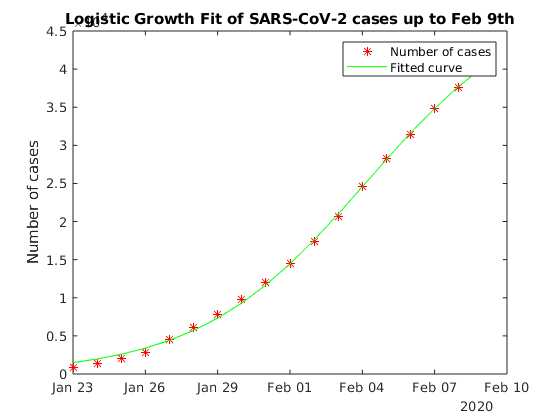


% As a formula:
logistic_fit_formula = @(t) Qinf./(1 + exp(-alpha*(t-thalf)));

% Plot
plot(cases_dates,cases_count,'*r',...
    cases_dates,Qpre,'green')
legend('Number of cases','Fitted curve');
title('Logistic Growth Fit of SARS-CoV-2 cases up to Feb 9th')
ylabel('Number of cases')

This model seems to fit the data much better.

## Logistic Growth Model Prediction

The curve fitting was done at the beginning of February. 

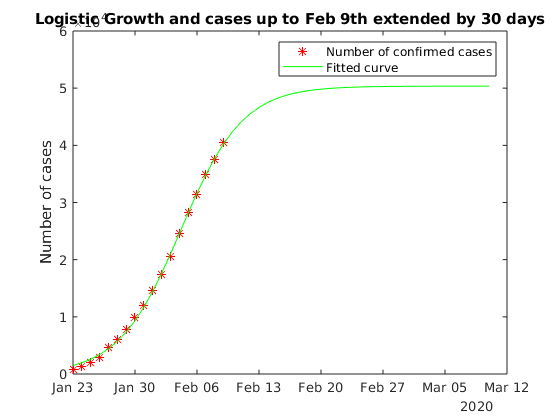

extra_days = 30;

extended_days_from_first_datapoint = [days_from_first_datapoint;max(days_from_first_datapoint)+(1:extra_days)'];
extended_cases_dates = [cases_dates;max(cases_dates)+days((1:extra_days)') ];
extended_cases_count = logistic_fit_formula(extended_days_from_first_datapoint);

plot(cases_dates,cases_count,'*r',...
    extended_cases_dates,extended_cases_count,'green')
legend('Number of confirmed cases','Fitted curve');
title("Logistic Growth and cases up to Feb 9th extended by "+extra_days +" days")
ylabel('Number of cases')

Fits the data better, but common sense might give us a different intuition for the future development of cases of the virus.

## Almost 30 lays later

Up to date data was retrieved from the Hong Kong government about cases of the SARS-CoV-2 cases in Mainland China [3]. So we can plot the new data against the old estimate

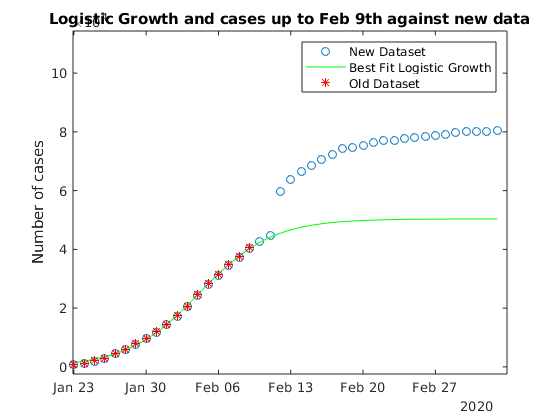

new_cases = read_hk_gov_covid_cases_in_mainland_china( ...
    "latest_situation_of_reported_cases_mainland_china_eng.csv");
new_cases = sortrows(new_cases,1,"descend");
new_cases_dates = flip(table2array(new_cases(:,1)));
new_cases_count = flip(table2array(new_cases(:,3)));

% Discard data earlier than our prevoius starting date
new_cases_count = new_cases_count(new_cases_dates >= cases_dates(1));
new_cases_dates = new_cases_dates(new_cases_dates >= cases_dates(1));
assert(new_cases_dates(1)==cases_dates(1));

new_days_from_first_datapoint = days(new_cases_dates - repelem(min(new_cases_dates),length(new_cases_dates))');

plot(new_cases_dates,new_cases_count,'o',...
    new_cases_dates,logistic_fit_formula(new_days_from_first_datapoint),'green', ...
    cases_dates,cases_count,"*r")
legend('New Dataset','Best Fit Logistic Growth', 'Old Dataset');
title("Logistic Growth and cases up to Feb 9th against new data")
ylabel('Number of cases')

xlim([datetime(2020,1,22,22,2,43)...
      datetime(2020,3,4,22,30,31)])
ylim([-2425 114319])

The big "jump" in the number of cases is when the the medical procedure for testing for the virus changes. This resulted in many more cases being recognized as of the SARS-CoV-2 infections.

Assuming that the the new SARS-CoV-2 test detects a number of cases proportional to the number of cases being detected before, we could try to correct for this change in testing procedure as follows: take the ratio between the actual number of cases  and the projected number as an adjustment factor. Then scale the curve and the values before the day of the jump by the adjustment factor.

We choose to adjust the preceding data so that our prediction is using current values.

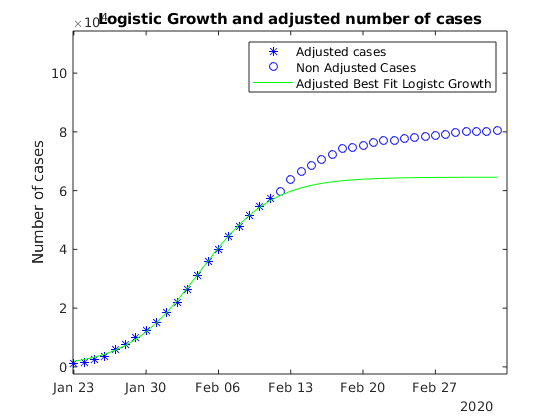

day_of_the_jump = datetime('12/02/2020','Format','dd/MM/yyyy');
day_of_the_jump_idx = find(new_cases_dates==day_of_the_jump);

adjustment_factor = new_cases_count(day_of_the_jump_idx)/logistic_fit_formula(day_of_the_jump_idx);

adjusted_new_cases = new_cases_count(new_cases_dates < day_of_the_jump);
adjusted_new_cases = adjusted_new_cases*adjustment_factor;
adjusted_dates = new_cases_dates(new_cases_dates < day_of_the_jump);

non_adjusted_cases = new_cases_count(new_cases_dates >= day_of_the_jump);
non_adjusted_dates = new_cases_dates(new_cases_dates >= day_of_the_jump);

plot(adjusted_dates, adjusted_new_cases,'*b',...
    non_adjusted_dates, non_adjusted_cases,'ob', ...
    new_cases_dates, ...
    logistic_fit_formula(new_days_from_first_datapoint)*adjustment_factor,'green')
legend('Adjusted cases','Non Adjusted Cases', 'Adjusted Best Fit Logistc Growth');
title("Logistic Growth and adjusted number of cases")
ylabel('Number of cases')

xlim([datetime(2020,1,22,22,2,43)...
      datetime(2020,3,4,22,30,31)])
ylim([-2425 114319])

Over all it seems like the model catpured the general pattern of the data, but it diddn't quite give us an acurate prediction. Even after introducing the ajustment factor ajustment factor.

## Towards a better model

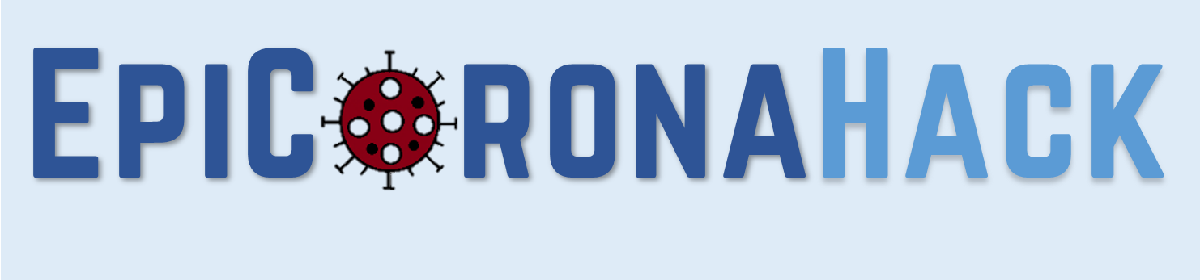

A frequently used model in epidemology is the SIR model. Its name comes from the fact that it describes the evolution over time of:

- $S$, the number of people succeptible to the disease. For new diseases like this one it is often assumed to be the entire population.

- $I$, the number of infected people.

- $R$, The number of people *removed *from the population, either by healing (assuming that the disease can't be contracted again) or otherwise

The relationships between the above quantities are give by the following system of differential equations:


$$\frac{dS}{dt}=-\frac{S}{N}\cdot \frac{R_0 }{D_I }\cdot I$$



$$\frac{dI}{dt}=$$

$$+\frac{S}{N}\cdot \frac{R_0 }{D_I }\cdot I-\frac{I}{D_I }$$



$$\frac{dR}{dt}=\frac{I}{D_I }$$


Where

- $R_0$ is the Basic Reproduction Number. Is the expected number of new cases generated by a single case. The news like to talk about this number.

-  $D_I$ is the he infectuos period. 

- $N$ is the total population.

In this model we assume that an individual shows symptoms and is contagious immediately after it coming in contact with the virus. There exist models such as the SEIR model that add an *Exposed *part of the population that has been exposed to the virus but might not show any symptoms yet, while already being contagious. Models of the sort are probably more accurate for the SARS-Cov-2 virus.

Unfortunately this model is not linear (because of the product of $S$ and $\left.I\right)$, and there is no known analytic solution.

## References

[1] Worldometers Dataset: [https://www.worldometers.info/coronavirus/coronavirus-cases/](https://www.worldometers.info/coronavirus/coronavirus-cases/)

[2] [James Conder (2020). fit_logistic(t,Q) (https://www.mathworks.com/matlabcentral/fileexchange/41781-fit_logistic-t-q), MATLAB Central File Exchange. Retrieved February 8, 2020.](https://www.mathworks.com/matlabcentral/fileexchange/41781-fit_logistic-t-q)

[3] Hong Kong Dataset: [https://data.gov.hk/en-data/dataset/hk-dh-chpsebcddr-novel-infectious-agent](https://data.gov.hk/en-data/dataset/hk-dh-chpsebcddr-novel-infectious-agent)